clear
simTimEnd=100;
samplingTime=0.01;

% Generating intial condition:
%In general, you can generate N
%random numbers in the interval (a,b) 
% with the formula r = a + (b-a).*rand(N,1).
a=-2;
b=2;

x1=a+(b-a)*rand();
x2=a+(b-a)*rand();

%Generating/Simulation some data to work with:

index=1; %Index to save some numbers 

for i=0:samplingTime:simTimEnd
    %The contious time model: 
    x1dot=2*x2(index,1);
    x2dot=-0.8*x1(index,1)+2*x2(index,1)-10*x1(index,1)^2*x2(index,1);
    
   %Using forward euler to get the states value: 
    index=index+1; 
    x1(index,1)=x1dot*samplingTime+x1(index-1,1);
    x2(index,1)=x2dot*samplingTime+x2(index-1,1);
end

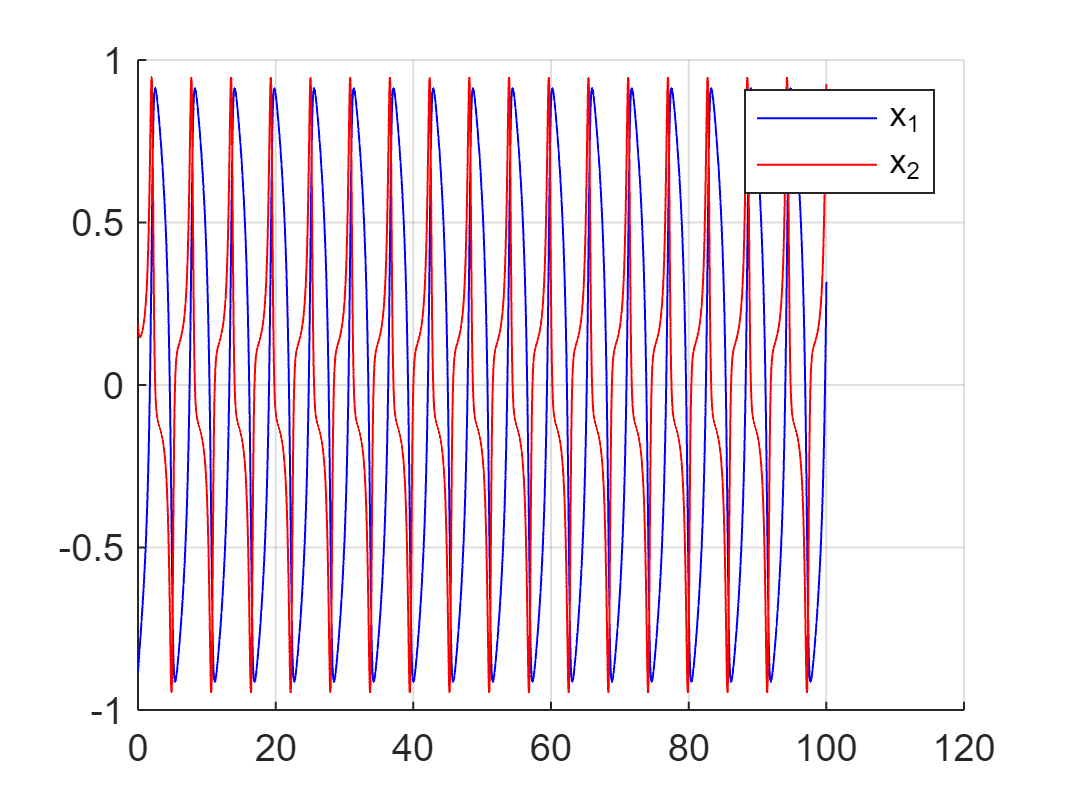

%Plotting the generated data:
time=0:samplingTime:simTimEnd+samplingTime; 

hold on 
plot(time,x1,'blue')
plot(time,x2,'red')
hold off 
grid
legend('x_1','x_2')

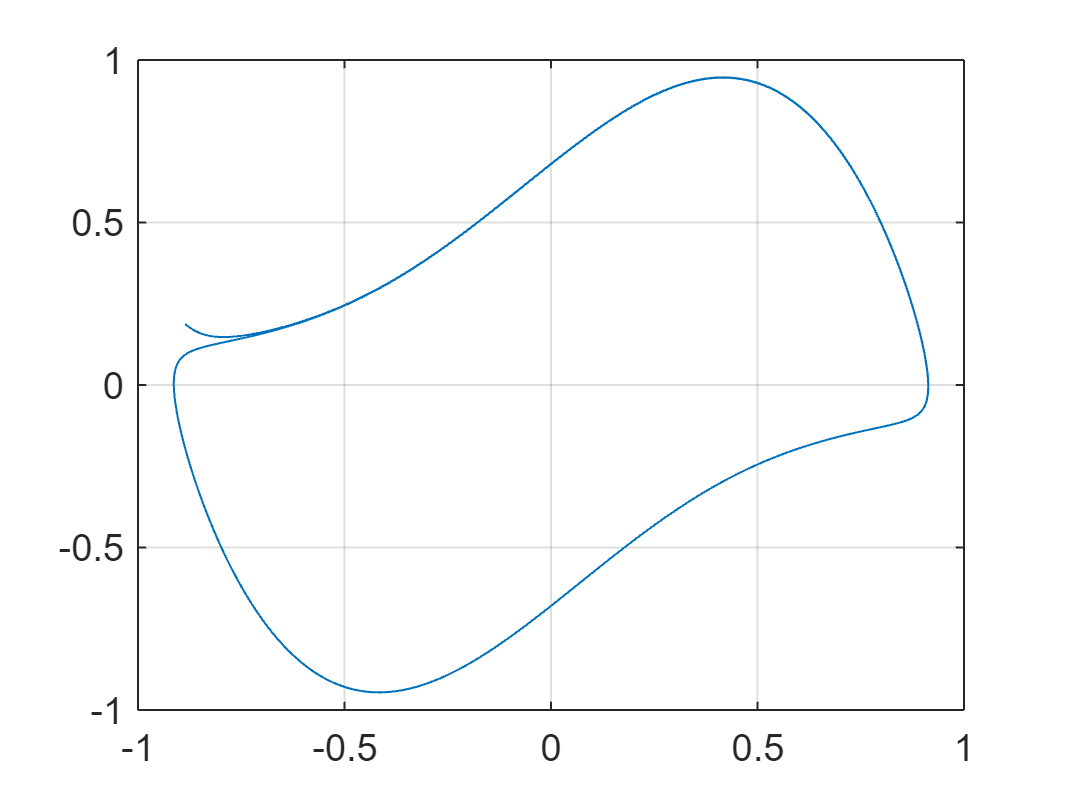



plot(x1,x2)
grid

%Making the Hankel matrix, which will be based on 5050 points, and a delay
%of 50  (therefore from 1 to 5000 or from 50 to 5049!:

index=1;

    for i=0:49 
        H(index,:)=x1(50-i:5049-i); 
        index=index+1;
        H(index,:)=x2(50-i:5049-i); 
        index=index+1;
    end 


%Takning the SVD of the Hankel matirx 
[U,S,V]=svd(H);


%Making the short version of the matrixs another group found that 12 
%is perfect 


    R=12; %Ens begræsning her 12!
    Vtilde=V(:,1:R);
    Stilde=S(1:R,1:R);
    Utilde=U(:,1:R);
   
    %Making the concurrent and predict V based on the small V
    Vtildepred=Vtilde(2:end,:);
    VtildeCon=Vtilde(1:end-1,:);
   
    %Approximation the koopman operation A:
    A=transpose(Vtildepred)*pinv(transpose(VtildeCon));
    

    %Making transformation such that it is possible to transfer the matrix
    %to the V subspace
    P=pinv(Utilde*Stilde);
    
    %Collecting all the simulated data into one matrix. 
    xAll=[x1';x2'];

    %The times series which is project to V, needs to have the same amout
    %of rows as H, as a delay of 50 was used and 2 states is present which
    %corresponds to 100 rows, therefore 99 present and the current sample
    %is used. The "model" was train on data from 0 to 5049, therefore the 
    % time series starts at 4951 to 5050 and builds up to 10000


for i=1:4950
    %Taking out the 100 samples
    xdata=xAll(:,4950+i:5049+i);

    %Projecting to the V subspace: 
    xProj=P*xdata'; 

    %Making prediction:
    PredictionV=A*xProj; 

    %Transforming the prediction back to the state space representation
    PreditionX=(Utilde*Stilde)*PredictionV;

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    PredictionXsave(:,i)=transpose(PreditionX(end,:));
end 

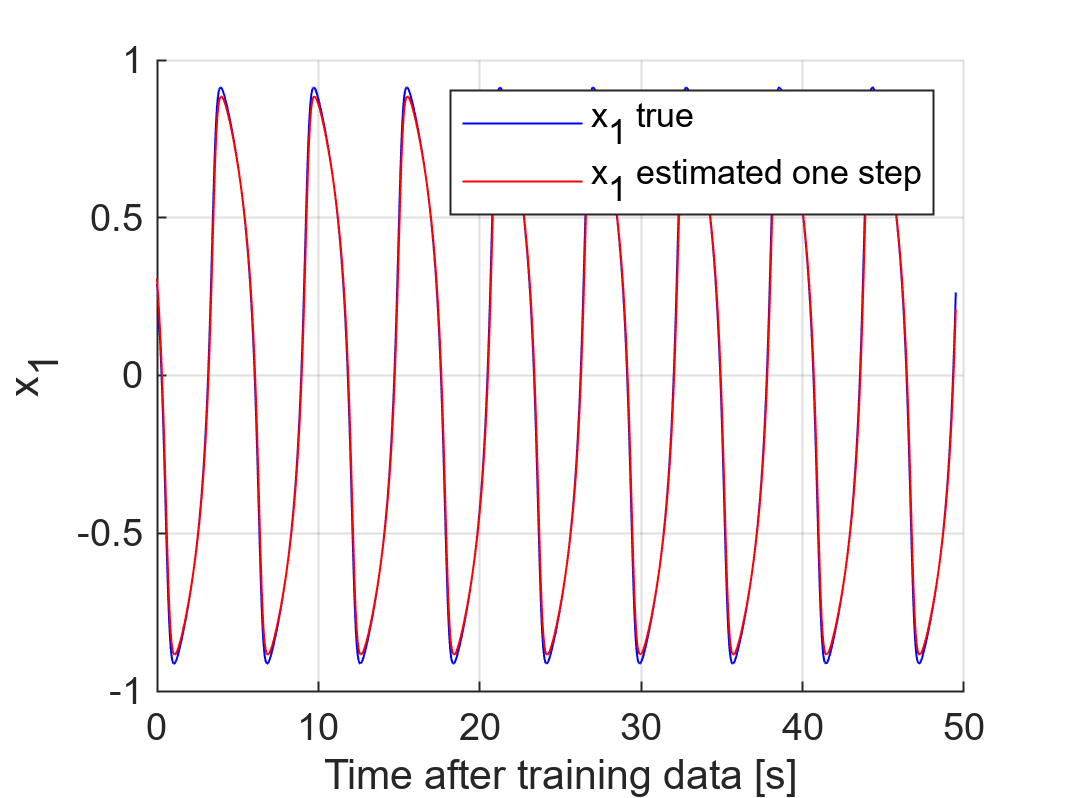

%Making plots of the estimation and the true simulated values for one step
%esitmation

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(time2,x1(5050:10000-1,1),'blue')
plot(time2,PredictionXsave(1,:),'red')
hold off 
grid
legend('x_1 true','x_1 estimated one step')
xlabel("Time after training data [s]")
ylabel('x_1')
ax=gca;
exportgraphics(ax,"x1_HAVOK_no_input.pdf")

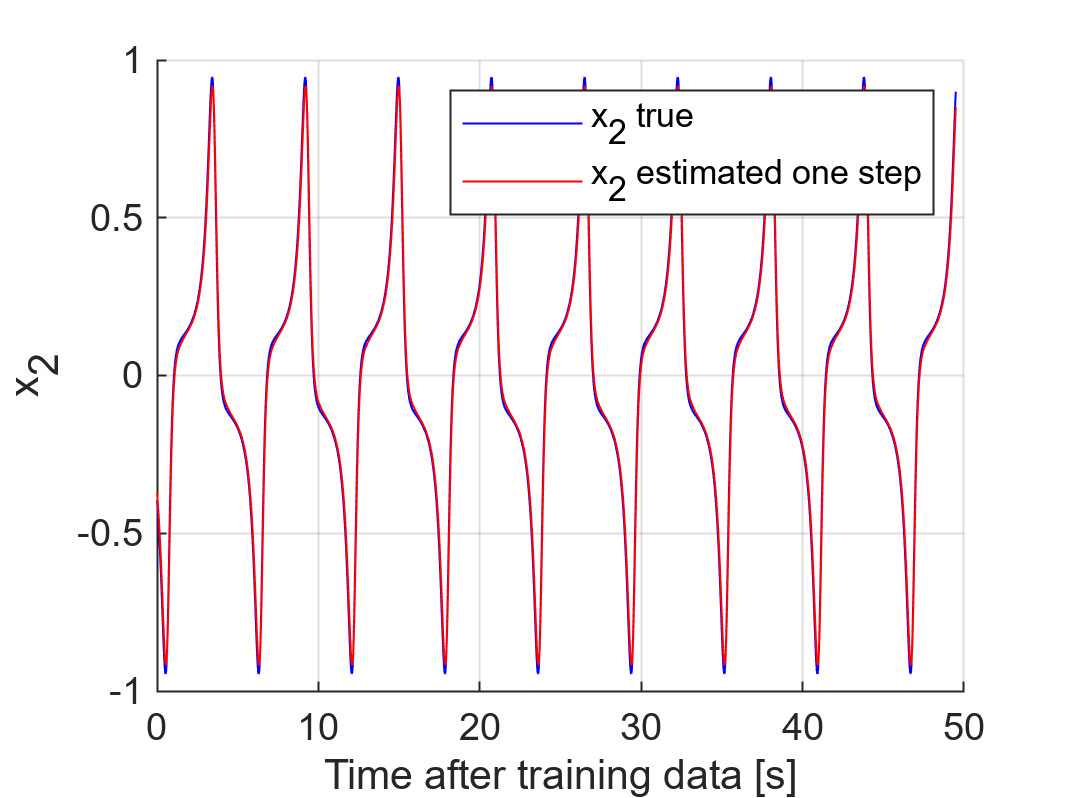



clf
hold on 
plot(time2,x2(5050:10000-1,1),'blue')
plot(time2,PredictionXsave(2,:),'red')
hold off 
grid
legend('x_2 true','x_2 estimated one step')
xlabel("Time after training data [s]")
ylabel('x_2')

ax=gca;
exportgraphics(ax,"x2_HAVOK_no_input.pdf")